# Preprocess Intracranial Hemorrhage Kaggle Data

% path = '/Volumes/med-kayvan-lab/Projects/Polytrauma/Data/Raw/subarachnoid_hematoma/kaggle_dataset/computed-tomography-images-for-intracranial-hemorrhage-detection-and-segmentation-1.0.0/subarachnoid_Patients_CT_brain/';
data_path = 'A:\Projects\Polytrauma\Data\Raw\subarachnoid_hematoma\kaggle_dataset\computed-tomography-images-for-intracranial-hemorrhage-detection-and-segmentation-1.0.0\subarachnoid_Patients_CT_brain\';
save_path = 'A:\Projects\Polytrauma\Data\Processed\hodgman\subarachnoid_hematoma\annotated_kaggle\';

save_path = 'A:\Projects\Polytrauma\Data\Processed\hodgman\subarachnoid_hematoma\annotated_kaggle\'


% get patient ids
pids = dir(data_path);
pids = pids(~strncmpi('.', {pids.name},1)); % remove files starting with '.'

% init
PatientsData = struct('brains', {},  'annots', {}, 'dicomImgs', {}, 'meta', {}, 'intensity_mean', {}, 'Pid', {}, 'Datatype', {});

% parse each patient's data
for p = 1 : length(pids)
    pid = pids(p).name;
    patient_files = dir([data_path pid]); % load patient file names
    
    % get reference images and masks
    patient_files = patient_files(contains({patient_files.name},'.jpg')); % keep only jpg patient_files
    mask_files = patient_files(contains({patient_files.name},'Seg')); % get masks
    ref_files = patient_files(~contains({patient_files.name},'Seg')); % remove masks from reference images
    
    % sort files by name numerically
    ref_files = natsortfiles(ref_files);
    mask_files = natsortfiles(mask_files);
    
    % combine individual slice images into single series
    ref_series = zeros(512, 512, length(ref_files));
    mask_series = zeros(512, 512, length(ref_files));
    
    % read, resize, and combine reference and mask images
    for i = 1 : length(ref_files)
    
        % compile reference slices
        ref_slice = imread([ref_files(i).folder '/' ref_files(i).name]);
        ref_slice = resize(ref_slice);
        ref_series(:,:,i) = ref_slice;
    
        % compile mask slices (when present) _HGE_Seg.jpg
        [filepath, slice_number, ext] = fileparts(ref_files(i).name);
    
        % find matching mask file, if present, and resize
        for j = 1 : length(mask_files)
            if slice_number == strrep(mask_files(j).name, '_HGE_Seg.jpg', '')
                mask_series(:,:,i) = resize(imread([mask_files(j).folder '/' mask_files(j).name]));
            end
        end
    end
    
    % rotate so nose points up
    [ref_series, mask_series] = rotate(ref_series, mask_series);

    % add to all-data struct
    PatientsData(p).dicomImgs = ref_series;
    PatientsData(p).annots = mask_series;
    PatientsData(p).Pid = str2num(pid);
end

% save to .mat file
fprintf(['Saving ....\n']);

Saving ....


fname = fullfile(save_path, ['PatientsData_kaggle.mat']);
save(fname, 'PatientsData', '-v7.3')

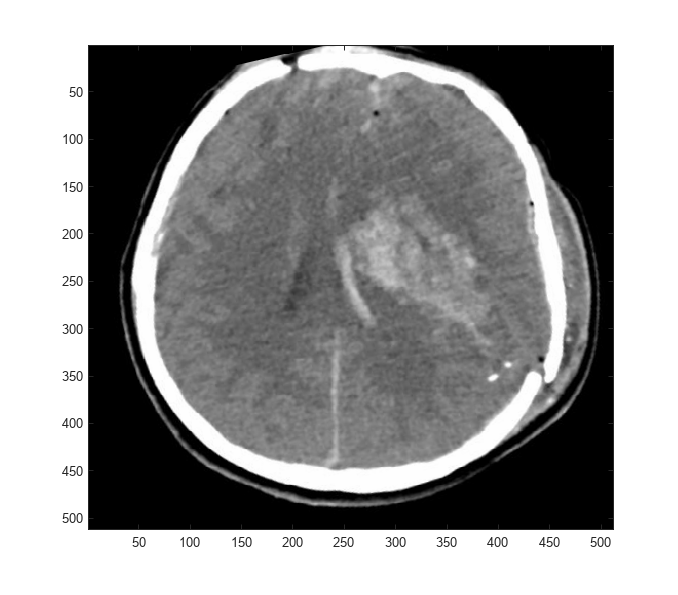

% visualize
for i = 1 : size(ref_series, 3)
    image(ref_series(:,:,i));
    colormap(gray);
    drawnow;
end

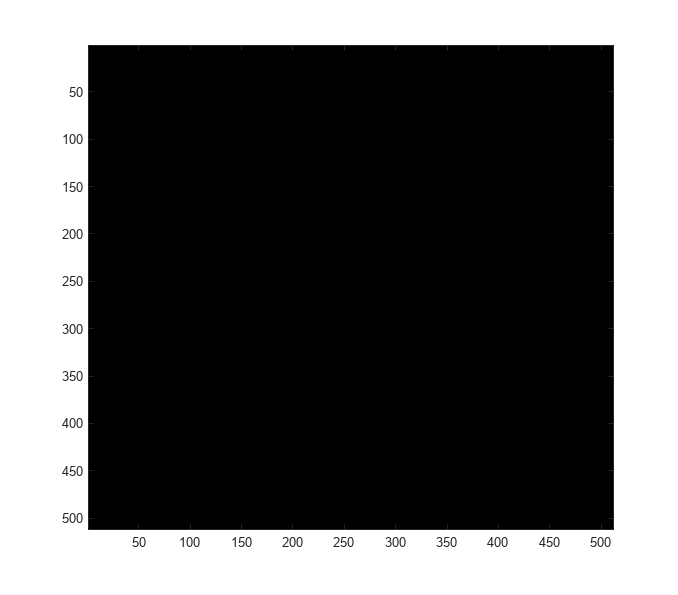


for i = 1 : size(mask_series, 3)
    image(mask_series(:,:,i));
    colormap(gray);
    drawnow;
end

function out = ROI(im,Size)
% Crop the image's center region with the given size
% 'Size' is the final size of the output image
  [h,w]=size(im);
  h_start=round((h-Size)/2);w_start=round((w-Size)/2);
  out=im(h_start+1:h_start+Size,w_start+1:w_start+Size);
end


function out_img = resize(img)
% resize image to 512x512
[h,w] = size(img);
delta_h = 0;
delta_w = 0;
if h<512
    delta_h = ceil((512-h)/2);
end

if w<512
    delta_w = ceil((512-w)/2);
end   

out_img = padarray(img, [delta_h, delta_w], img(1,1));
out_img = ROI(out_img, 512);
end


function [refs, masks] = rotate(refs, masks)
% rotate
    temp = refs>250; % change threshold?
    s = regionprops3(temp,'Volume','Orientation','Centroid');
    [~, ind] = sort([s.Volume]);
    rotate_angle = -1*s.Orientation(ind(end));
    center = s.Centroid(ind(end),1:2);
    refs = img_rotate(refs, center, rotate_angle, 'bilinear');
    masks = img_rotate(masks, center, rotate_angle, 'bilinear');
end